## **Define f(t)**

Ts = 0.01;       % seconds sample
T = 2;          % seconds
t= 0: Ts: T - Ts

t =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


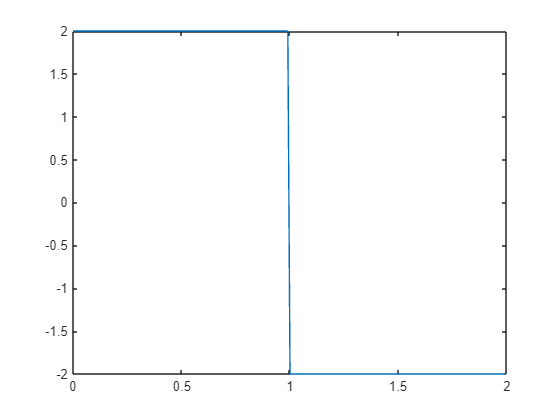

f(t < T/2) = 2;
f((t>=T/2) & (t<T)) = -2;
plot(t,f)

Calculate **real **valued coefficients

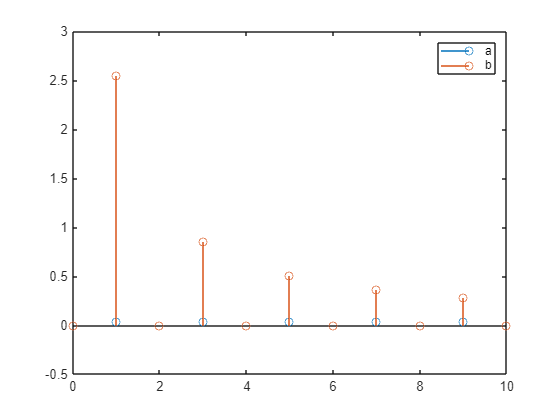

N = 10;
a = zeros(1, N+1);
b = zeros(1, N+1);

for n = 0: N
    a(n+1) = (2*Ts/T)*sum(f.*cos((2*pi*t*n)/T));
    b(n+1) = (2*Ts/T)*sum(f.*sin((2*pi*t*n)/T));
end

stem(0:N,a)
hold on 
stem(0:N,b)
hold off
legend('a','b')

### **fourier series **

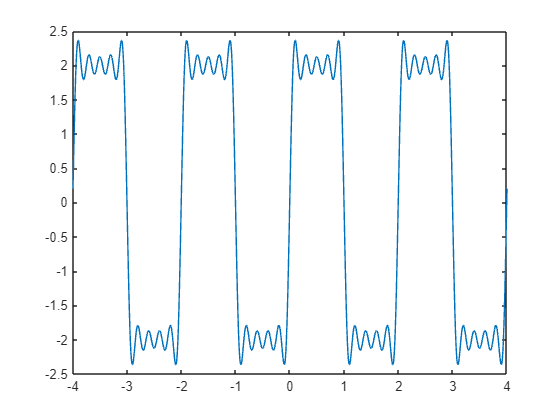

tsyn= -2*T: Ts: 2*T;
fs = (a(1)/2) * ones(size(tsyn));
for n =1: N
    fs = fs + a(n + 1)*cos((2*pi*tsyn*n)/T) + b(n + 1) *sin((2*pi*tsyn*n)/T);
end
plot(tsyn,fs)

**Complex fourier series**

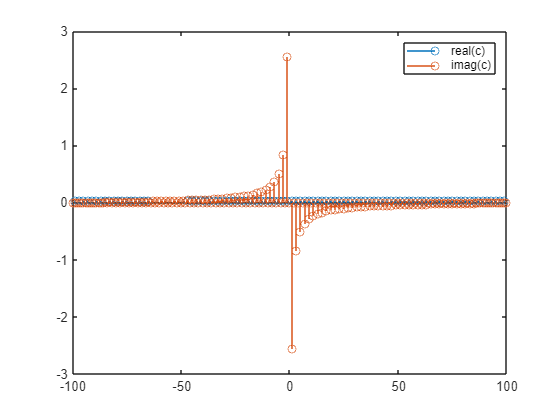

N = 100;
c = zeros(1, 2*N+1);

for n = -N: N
    c(n+N+ 1) = (2*Ts/T)*sum(f.*exp(-1i*2*pi*t*n/T));

end

stem(-N:N,real(c))
hold on 
stem(-N:N,imag(c))
hold off
legend('real(c)','imag(c)')

**Exponent fourier series**

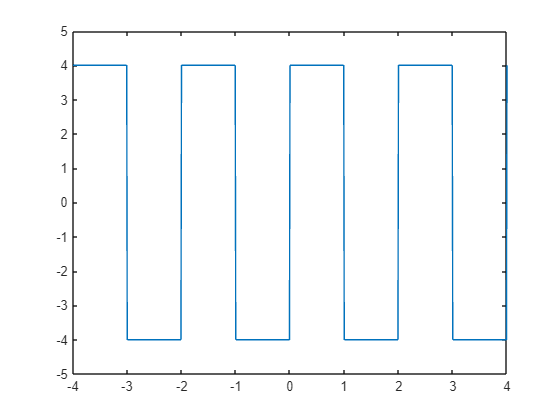

tsyn= -2*T: Ts: 2*T;
fs = zeros(size(tsyn));
for n = -N: N
    fs = fs + (c(n + N + 1)*exp(1i*2*pi*tsyn*n/T));
end
plot(tsyn,real(fs)) % if instead of real(fs) we type just fs then we will get an error because of the complex part of it

The end